# Savitzky-Golay Filters

Savitzky-Golay filters are smoothing filters based on locally fitting a polynomial to the data at each point. Refer to the figure below.

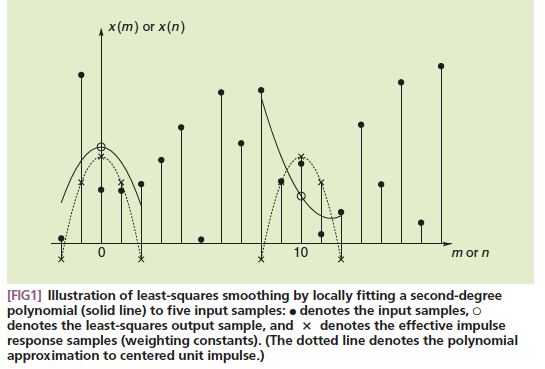

It may seem that fitting a polynomial to a signal may not be a linear filtering operation. For example, doesn't the polynomial change at every point? We will explore this issue in this lab.

To be specific, consider the following filtering scheme where


$$y[n] = \mathcal{P}\left\{x[n-2], \,x[n-1], \,x[n], \,x[n+1], \,x[n+2]\right\} \ \text{.}$$


The function $\mathcal{P}(\cdot)$ perform 


$$p[k] = a_0 + a_1 k + a_2 k^2 \ \text{for} \ (-2 \le k \le 2)$$


on the local input and returns $p[0] = a_0$. 

Your task is to develop some code to find the solution for y[0] and y[1]. You should find that your method of solution is actually independent of the signal! How can that be? More specifically, you should be able to create a five-tap FIR filter to compute y[n] from x[n].

You may find the following information relevant.

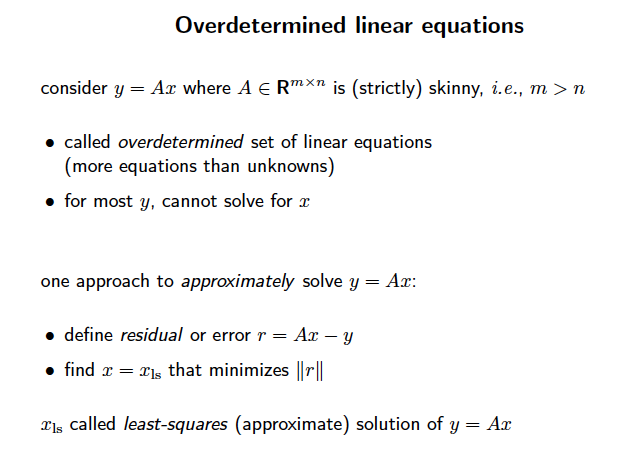

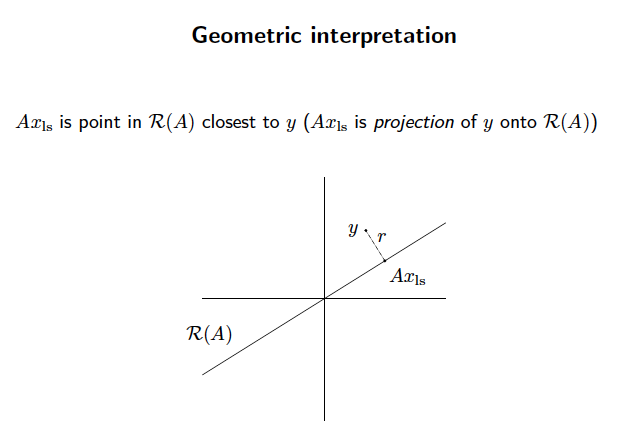

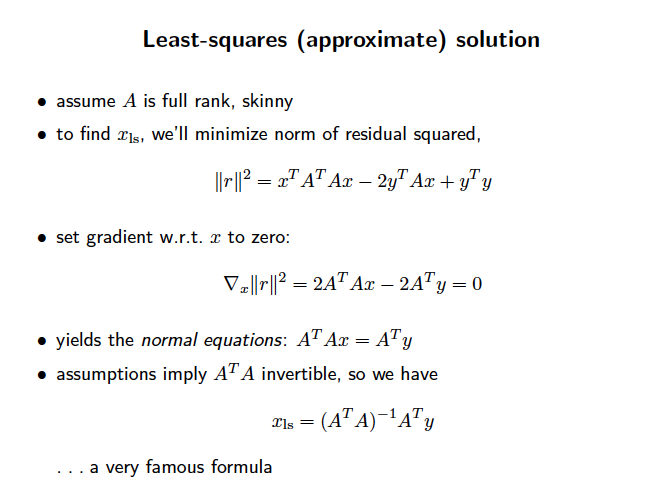

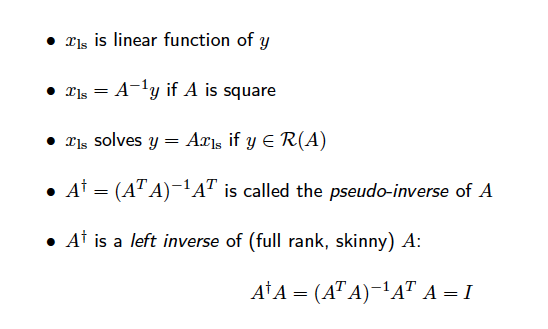

Put your code here. Write your code so that the polynomial order (in this case 2) can be varied as well as the number of samples that are fit (this should be an odd number, in this case 5). 

clear all

function res = SGFilter (sigIn, nl, nr, order)

% matrix A
A = ones (nl+nr+1, order+1);
for j = order:-1:1
  A(:, j) = (-nl:nr)' .* A (:, j+1);
end
% 
% res = sigIn;
% n = size (sigIn);
% for i = 1+nl:n-nr
%   res (i) = c' * f (i-nl:i+nr);
% end




What are the five taps of the filter?

Put your answer here:

Compute and plot the impulse response of the system.

Put your code here:

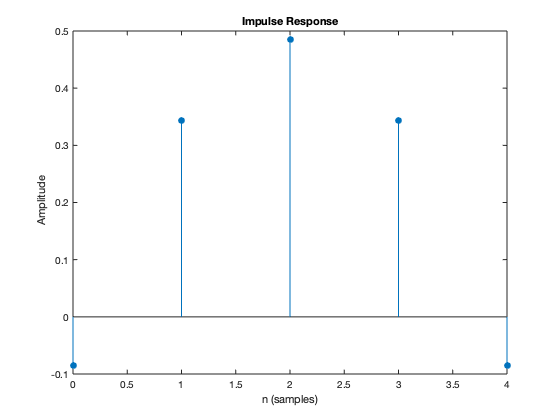

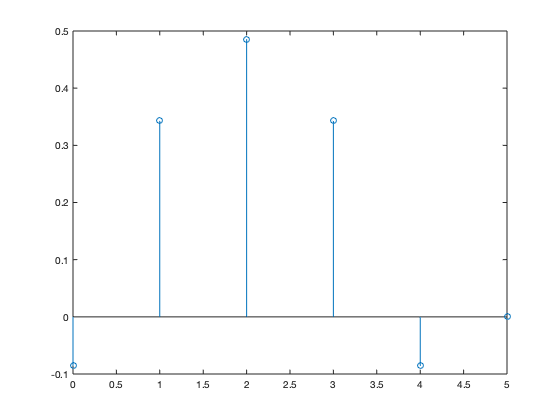

Test your filter on the following sinusoidal signal with noise. Use a polynomial order of 2 and the number of samples as 10.

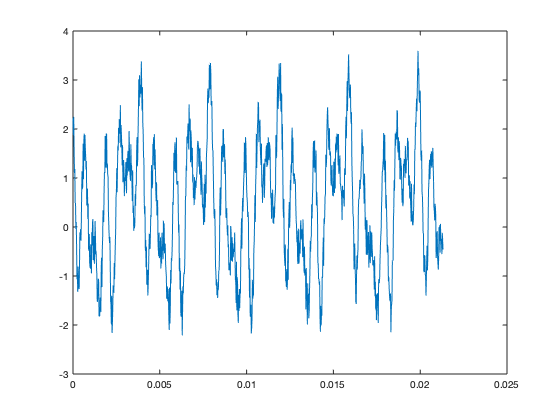

Fs = 48000 ;
tAxis = (0:1/Fs:1) ;
freq1 = 1000 ; freq2 = 250 ; freq3 = 1500 ; 
mySig = cos(2*pi*freq1*tAxis + pi/3) + ...
        cos(2*pi*freq2*tAxis + pi/4) + ...
        cos(2*pi*freq3*tAxis + pi/5) ;
noiseSig = rand(size(tAxis)) ;
mySigNoise = mySig + noiseSig ;
numSamp = 1024 ;
figure ;
plot(tAxis(1:numSamp),mySigNoise(1:numSamp))

Apply your filter to the signal mySigNoise using Matlab's filter operation and plot the smoothed signal and the original signal together.

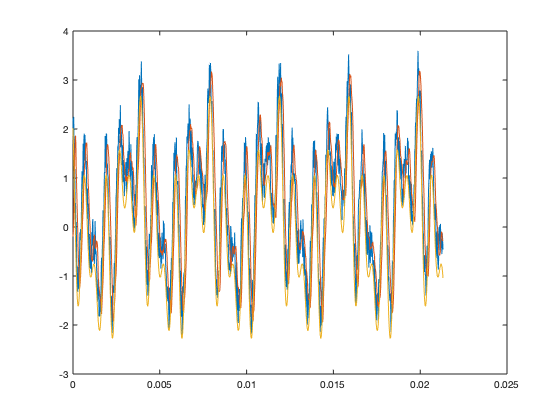

% Put your filtering code here:
% your code


figure ;
plot(tAxis(1:numSamp),mySigNoise(1:numSamp))
hold on
plot(tAxis(1:numSamp), mySigNoiseSmooth(1:numSamp))
plot(tAxis(1:numSamp), mySig(1:numSamp))

Listen to the signals. Is there less noise?

soundsc(mySig,Fs)
pause(1.5)
soundsc(mySigNoise,Fs)
pause(1.5)
soundsc(mySigNoiseSmooth,Fs)


For sinusoidal signals, we can explore sparsity in the frequency domain. This has not been taught - it is just for fun.

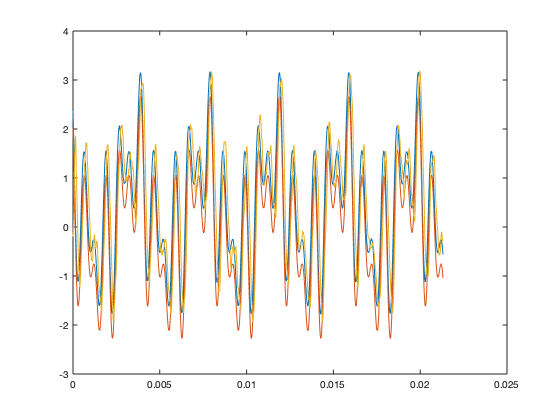

sigFFT = fft(mySigNoise) ;
freqAxis = [0:length(sigFFT)-1]*Fs/length(sigFFT) ;
% figure
% plot(freqAxis,abs(sigFFT))
magicNum = 140 ; % around this value is good
sigFFTSparse = SoftThresh(sigFFT,magicNum) ;
mySigSparse = real(ifft(sigFFTSparse)) ;

figure
plot(tAxis(1:numSamp),mySigSparse(1:numSamp))
hold on
plot(tAxis(1:numSamp),mySig(1:numSamp))
plot(tAxis(1:numSamp), mySigNoiseSmooth(1:numSamp))

Listen to the sparse signal:

soundsc(mySig,Fs)
pause(1.5)
soundsc(mySigNoise,Fs)
pause(1.5)
soundsc(mySigNoiseSmooth,Fs)
pause(1.5)
soundsc(mySigSparse,Fs)


To complete this lab, please create a Savitzky-Golay filter for a polynomial order of 10 and a number of samples equal to 55. The conditioning of the matrix will be poor when computing the inverse, but Matlab on my computer still provides a good result.

Put your code here and put a screen shot of your impulse response in your blog!